# 1.3.08 Символьная алгебра

**Практическое занятие**

## **Переменные, выражения, функции и уравнения**

pi/6 + pi/4

ans = 1.3090

sym(pi/6) + sym(pi/4)

$$ans = \frac{5\,\pi }{12}$$

syms x y 
log(x) + exp(y)

$$ans = {\mathrm{e}}^{y}+\log\left(x\right)$$

Задание кусочно-линейных функций

y(x) = piecewise(x<0, -1, x>0, 1)

$$y(x) = \left\{ \begin{array}{cl} -1 & \text{ if }x<0\\ 1 & \text{ if }0<x \end{array}\right.$$

Задание функции. Найдите значение функции при $x=-5$.

syms f(x)
f(x) = x^4-2*x^3+6*x^2-2*x+10

$$f(x) = x^{4}-2\,x^{3}+6\,x^{2}-2\,x+10$$


f(-5)

$$ans = 1045$$

Найдите пересечение прямых $y_1$ и $y_2$ используя `solve()`.

syms y1 y2
y1 = x+3; y2 = 3*x;
solve(y1 == y2)

$$ans = \frac{3}{2}$$

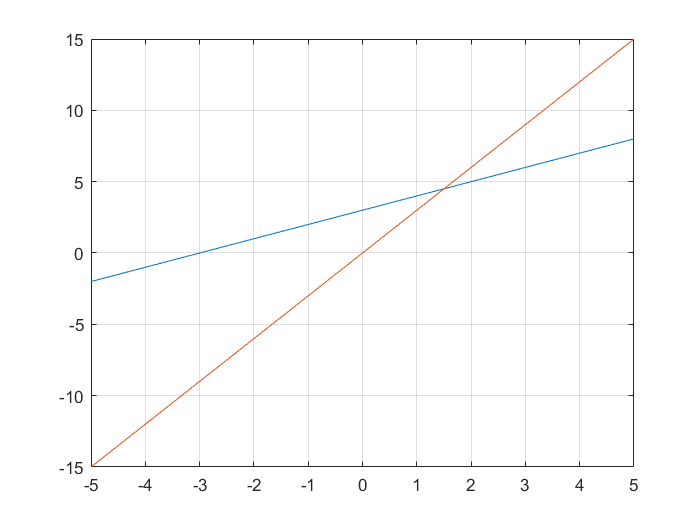

fplot(y1),hold on,fplot(y2),grid,hold off

Сделайте предположение относительно значения символьной переменной. Существует 4 решения уравнения $x^4 =1$, два действительных и два комплексных. Предположим, что x - действительное число, причем $x>0$, тогда существует только одно решение.

syms x
solve(x^4 == 1)

$$ans = \left(\begin{array}{c} -1\\ 1\\ -\mathrm{i}\\ \mathrm{i} \end{array}\right)$$

assume(x,'real')
assumeAlso( x > 0)
assumptions(x)

$$ans = \left(\begin{array}{cc} x\in \mathbb{R} & 0<x \end{array}\right)$$

solve(x^4 == 1)

$$ans = 1$$

assume(x,'clear')

## **Подстановки и решение уравнений**

Сделайте подставновку в символьное выражений. Подставьте значение $x=x_0 -1$ в выражение $x^2 +1$

syms x xo
subs(x^2+1,x,xo-1)

$$ans = {\left(\mathrm{xo}-1\right)}^{2}+1$$

Множественная подстановка. Рассчитайте значение выражения $\mathrm{cos}\left(a\right)+\mathrm{sin}\left(b\right)-e^{2c}$, подставив следующие значения $a=\frac{\pi }{2}$, $b=\frac{\pi }{4}$, $c=-1$.

syms a b c
subs(cos(a) + sin(b) - exp(2*c), [a b c], [pi/2 pi/4 -1])

$$ans = \frac{\sqrt{2}}{2}-{\mathrm{e}}^{-2}$$

Задайте уравнение $9x^2 +1=0$ и решите его.

solve(9*x^2 - 1 == 0)

$$ans = \left(\begin{array}{c} -\frac{1}{3}\\ \frac{1}{3} \end{array}\right)$$

Решите квадратное уравнение ${\mathit{ax}}^2 +bx+c=0$ аналитически, и найдите его корни при $a=9,\;b=0,\;c=-1$.

eqn = a*x^2 + b*x + c == 0;
sol = solve(eqn) 

$$sol = \left(\begin{array}{c} -\frac{b+\sqrt{b^{2}-4\,a\,c}}{2\,a}\\ -\frac{b-\sqrt{b^{2}-4\,a\,c}}{2\,a} \end{array}\right)$$

subs(sol,[a b c],[9 0 -1])

$$ans = \left(\begin{array}{c} -\frac{1}{3}\\ \frac{1}{3} \end{array}\right)$$

Когда требуется высокая точность вычислений, для решения уравнений следует использовать арифметику переменной точности.

Например график функции $f\left(x\right)=6x^7 -2x^6 +3x^3 -8$ почти параллелен оси $x$ в окрестности своих корней. Как в таком случае найти решение достаточно точно?

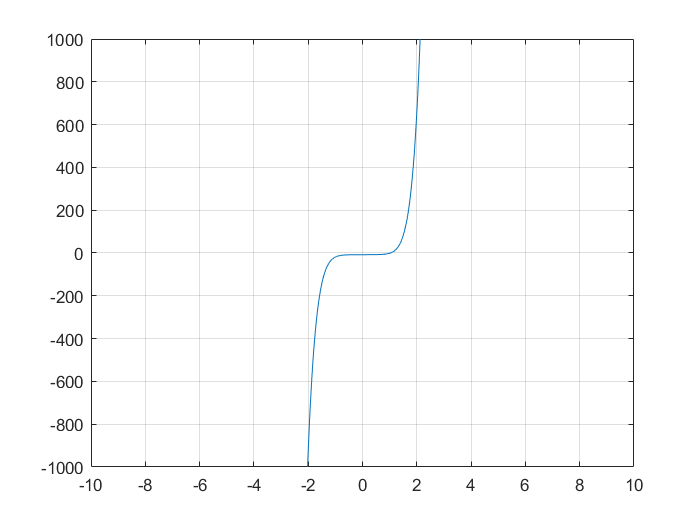

syms x f(x)
% assume(x>0)
f(x) = 6*x^7-2*x^6+3*x^3-8;
fplot(f)
xlim([-10 10])
ylim([-1e3 1e3])
grid

doubleSol = roots([6 -2 0 0 3 0 0 -8]) %  двойная точность

doubleSol =    1.0240 + 0.0000i
   0.7652 + 0.8319i
   0.7652 - 0.8319i
  -0.8808 + 0.5043i
  -0.8808 - 0.5043i
  -0.2297 + 0.9677i
  -0.2297 - 0.9677i


symsSol = solve(f) % точное решение. Объект symsSol хранит внутри себя нули функции для дальнейших символьных вычислений

$$symsSol = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right)\\ \mathrm{root}\left(\sigma_{1},z,5\right)\\ \mathrm{root}\left(\sigma_{1},z,6\right)\\ \mathrm{root}\left(\sigma_{1},z,7\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{7}-\frac{z^{6}}{3}+\frac{z^{3}}{2}-\frac{4}{3} \end{array}$$

vpaSol = vpasolve(f) % переменная точность

$$vpaSol = \left(\begin{array}{c} 1.0240240759053702941448316563337\\ -0.88080620051762149639205672298326+0.50434058840127584376331806592405\,\mathrm{i}\\ -0.88080620051762149639205672298326-0.50434058840127584376331806592405\,\mathrm{i}\\ -0.22974795226118163963098570610724+0.96774615576744031073999010695171\,\mathrm{i}\\ -0.22974795226118163963098570610724-0.96774615576744031073999010695171\,\mathrm{i}\\ 0.7652087814927846556172932675903+0.83187331431049713218367239317121\,\mathrm{i}\\ 0.7652087814927846556172932675903-0.83187331431049713218367239317121\,\mathrm{i} \end{array}\right)$$

assume(x,'clear')

## **Упрощение выражений**

Упростите выражение $\left(x-1\right)\left(x+1\right)\left(x^2 +x+1\right)\left(x^2 +1\right)\left(x^2 -x+1\right)\left(x^4 -x^2 +1\right)\;$и убедитесь, что оно равно to $x^{12} +1$.

simplify((x - 1)*(x + 1)*(x^2 + x + 1)*(x^2 + 1)*(x^2 - x + 1)*(x^4 - x^2 + 1))

$$ans = x^{12}-1$$

MATLAB автоматически применяет тригонометрические тождества для упрощения выражений, например, мы знаем, что:


$$\begin{array}{l}
{\mathit{sin}}^2 \left(x\right)=\frac{1-\mathit{cos}\left(2x\right)}{2}\\
{\mathit{sin}}^2 \left(x\right)+{\mathit{cos}}^2 \left(x\right)=1\\
\mathit{sin}\left(2x\right)=2\mathit{sin}\left(x\right)\mathit{cos}\left(x\right)
\end{array}$$
 

Проверим:

combine(2*sin(x)*cos(x) + (1- cos(2*x))/2 + cos(x)^2,'sincos')

$$ans = \sin\left(2\,x\right)+1$$

Разложите на многочлены выражения.

syms x y
factor(y^6-x^6)

$$ans = \left(\begin{array}{ccccc} -1 & x-y & x+y & x^{2}+x\,y+y^{2} & x^{2}-x\,y+y^{2} \end{array}\right)$$


f(x) = (x^3 + 7);
expand(f(y-1))

$$ans = y^{3}-3\,y^{2}+3\,y+6$$

Найдите суперпозицию функций $f\left(g\left(x\right)\right)$.

f(x) = sqrt(log(x));
g(x) = sqrt(1-x);
h = compose(g,f,x)

$$h(x) = \sqrt{1-\sqrt{\log\left(x\right)}}$$

## **Вычисления (дифференцирование, интегрирование, пределы, ряды)**

Найдите производную $\frac{d}{\mathit{dx}}\left(\mathrm{sin}\left(x\right)\right)$.

diff(sin(x))

$$ans = \cos\left(x\right)$$

Найдите производную сложной функции $\frac{d}{\textrm{dx}}\left(x^2 +\mathit{sin}\left(2x^4 \right)+1\right)$.

diff(x^2+sin(2*x^4)+1,x)

$$ans = 2\,x+8\,x^{3}\,\cos\left(2\,x^{4}\right)$$

Найдите неопределенный интеграл$\int f\left(x\right)\textrm{dx}$ для $f\left(x\right)=e^{\frac{-x^2 }{2}}$.

int(exp(-x^2/2),x)

$$ans = \frac{\sqrt{2}\,\sqrt{\pi }\,\mathrm{erf}\left(\frac{\sqrt{2}\,x}{2}\right)}{2}$$

Найдите определенный интеграл $\int_a^b f\left(x\right)\mathit{dx}$ для $f\left(x\right)=x\cdot \mathrm{log}\left(1+x\right)$ от 0 до 1.

int(x*log(1+x),0,1)

$$ans = \frac{1}{4}$$

Докажите, что $\frac{\mathit{sin}\left(x\right)}{x}=1$ при $x=0$ с помощью разложения в ряд Тейлора  $\sum {\left(x-a\right)}^n \frac{f^{\left(n\right)} \left(a\right)}{n!}$ for $f\left(x\right)=\frac{\mathit{sin}\left(x\right)}{x}$  в окрестности точки $x=0$.

syms x 
T = taylor(sin(x)/x)

$$T = \frac{x^{4}}{120}-\frac{x^{2}}{6}+1$$

subs(T,x,0)

$$ans = 1$$

Докажите, что функция $\mathit{tan}\left(x\right)$ имеет разрыв в точке $x=\frac{\pi }{2}$ , показав, что пределы справа и слева не равны. $\lim_{{x\to \frac{\pi }{2}}^+ } \mathit{tan}\left(x\right)\not= \lim_{{x\to \frac{\pi }{2}}^- } \mathit{tan}\left(x\right)$.

limit(tan(x),x,pi/2,'left')

$$ans = \infty$$

limit(tan(x),x,pi/2,'right')

$$ans = -\infty$$

limit(tan(x),x,pi/2)

$$ans = \mathrm{NaN}$$

## **Дифференциальные уравнения**

Решите обыкновенное дифференциальное уравнение первного порядка  $\frac{\mathit{dy}}{\mathit{dx}}=-\mathit{ay}$.

syms a b y(x)
dsolve(diff(y) == -a*y)

$$ans = C_{4}\,{\mathrm{e}}^{-a\,x}$$

Решите то же самое ОДУ при следующих начальных условиях: $y\left(0\right)=b$.

dsolve(diff(y)== -a*y,y(0)==b)

$$ans = b\,{\mathrm{e}}^{-a\,x}$$

Решите систему ОДУ $\frac{\textrm{dx}}{\textrm{dt}}=\textrm{y}$ и $\frac{\textrm{dx}}{\textrm{dt}}=x$.

syms x(t) y(t)
z = dsolve(diff(x) == y, diff(y) == -x);
disp([z.x;z.y])

$$\left(\begin{array}{c} C_{7}\,\cos\left(t\right)+C_{6}\,\sin\left(t\right)\\ C_{6}\,\cos\left(t\right)-C_{7}\,\sin\left(t\right) \end{array}\right)$$

## **Линейная алгебра**

Выполните матричное умножение $\mathit{Ax}=b$, где $A=\left\lbrack \begin{array}{cc}
a & b\\
c & d
\end{array}\right\rbrack$ и $x=\left\lbrack \mathit{x1},\mathit{x2}\right\rbrack$

syms a b c d
syms x1 x2
x = [x1; x2];
A = [a b ; c d];
b = A*x

$$b = \left(\begin{array}{c} a\,x_{1}+b\,x_{2}\\ c\,x_{1}+d\,x_{2} \end{array}\right)$$

Найдите детерминант матрицы A.

det(A)

$$ans = a\,d-b\,c$$

Найдите собственные значения матрицы A.

lambda = eig(A)

$$lambda = \left(\begin{array}{c} \frac{a}{2}+\frac{d}{2}-\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2}\\ \frac{a}{2}+\frac{d}{2}+\frac{\sqrt{a^{2}-2\,a\,d+d^{2}+4\,b\,c}}{2} \end{array}\right)$$

## **Графика**

Пакет Symbolic Math Toolbox позволяет строить 2D и 3D-графики по аналитическим выражениям.

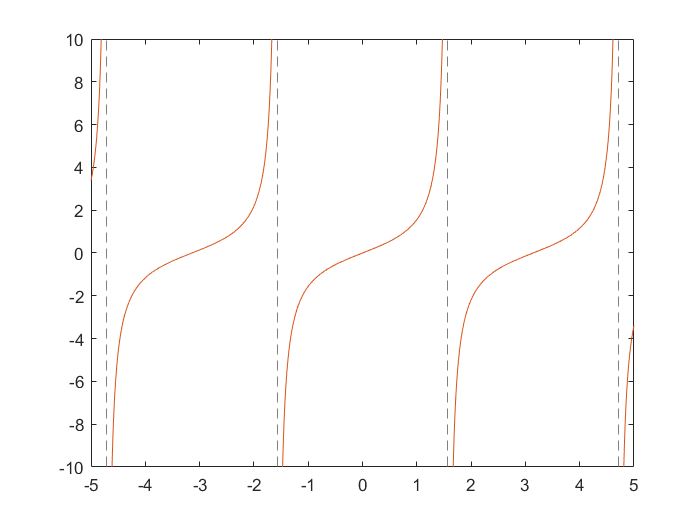

fplot(tan(x))

Постройте параметрическую кривую $x\left(t\right)=t\cdot \mathit{sin}\left(5t\right)$ и $y\left(t\right)=t\cdot \mathit{cos}\left(5t\right)$.

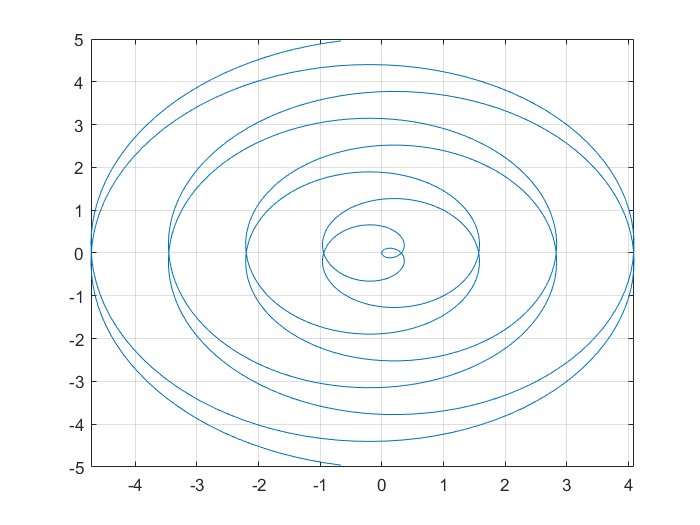

syms t
x = t*sin(5*t); 
y = t*cos(5*t);
fplot(x, y)
grid on

Постройте трёхмерную параметрическую кривую $x\left(t\right)=e^{\frac{\left|t\right|}{10}} \mathit{sin}\left(5\left|t\right|\right)$, $y\left(t\right)=e^{\frac{\left|t\right|}{10}} \mathit{cos}\left(5\left|t\right|\right)$ и $z\left(t\right)=t$ на интервале `[-10,10] прерывистой красной линией`.

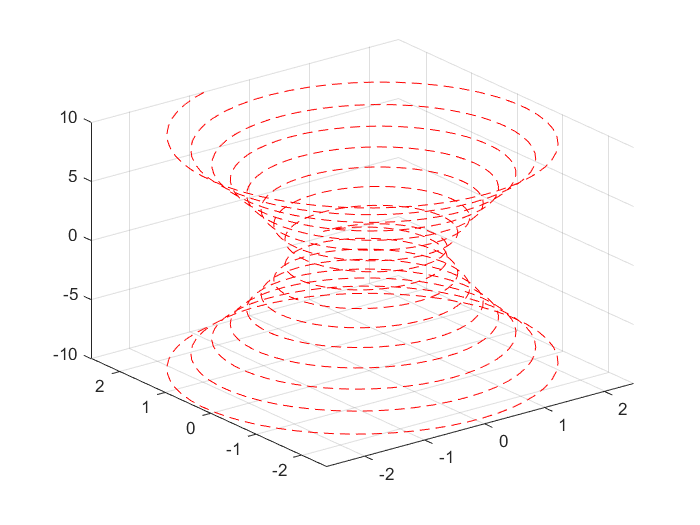

syms t
xt = exp(abs(t)/10).*sin(5*abs(t));
yt = exp(abs(t)/10).*cos(5*abs(t));
zt = t;
h = fplot3(xt,yt,zt, [-10,10],'--r');

Постройте 3D-поверхность $f\left(x,y\right)=\mathit{sin}\left(x\right)+\mathit{cos}\left(y\right)$.

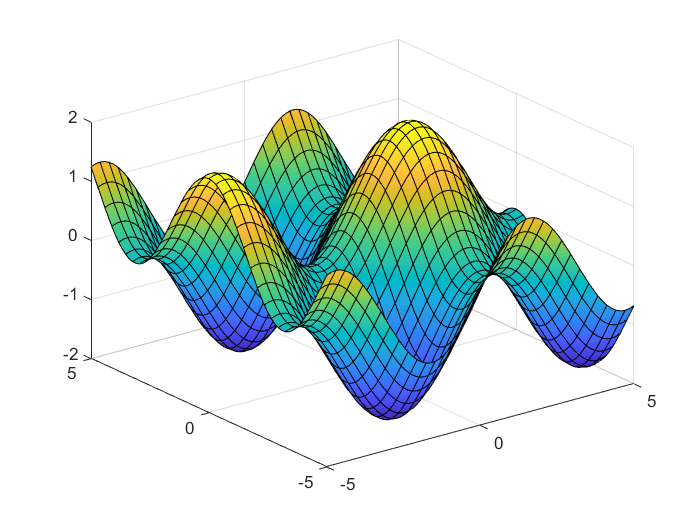

syms x y
fsurf(sin(x) + cos(y))

Постройте двумерные контуры этой же поверхности.

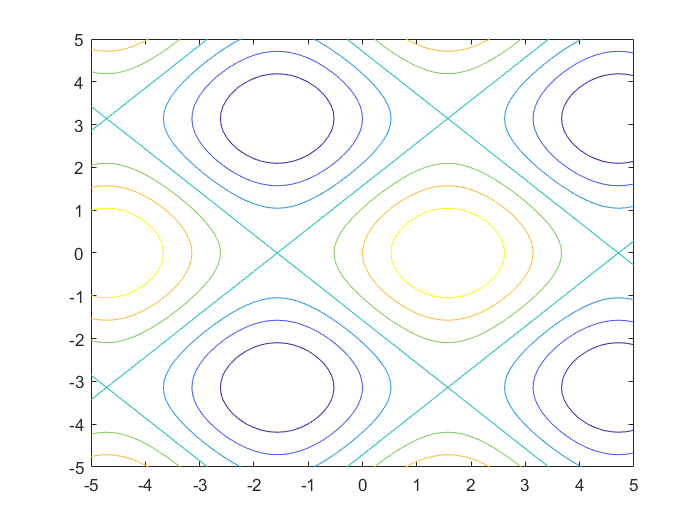

fcontour(sin(x) + cos(y))